# 不可逆单闭环直流调速系统静特性的研究

数据来源：xin❤️

sheets=sheetnames("exprData.xlsx");

## 绘制开环机械特性和单闭环静特性

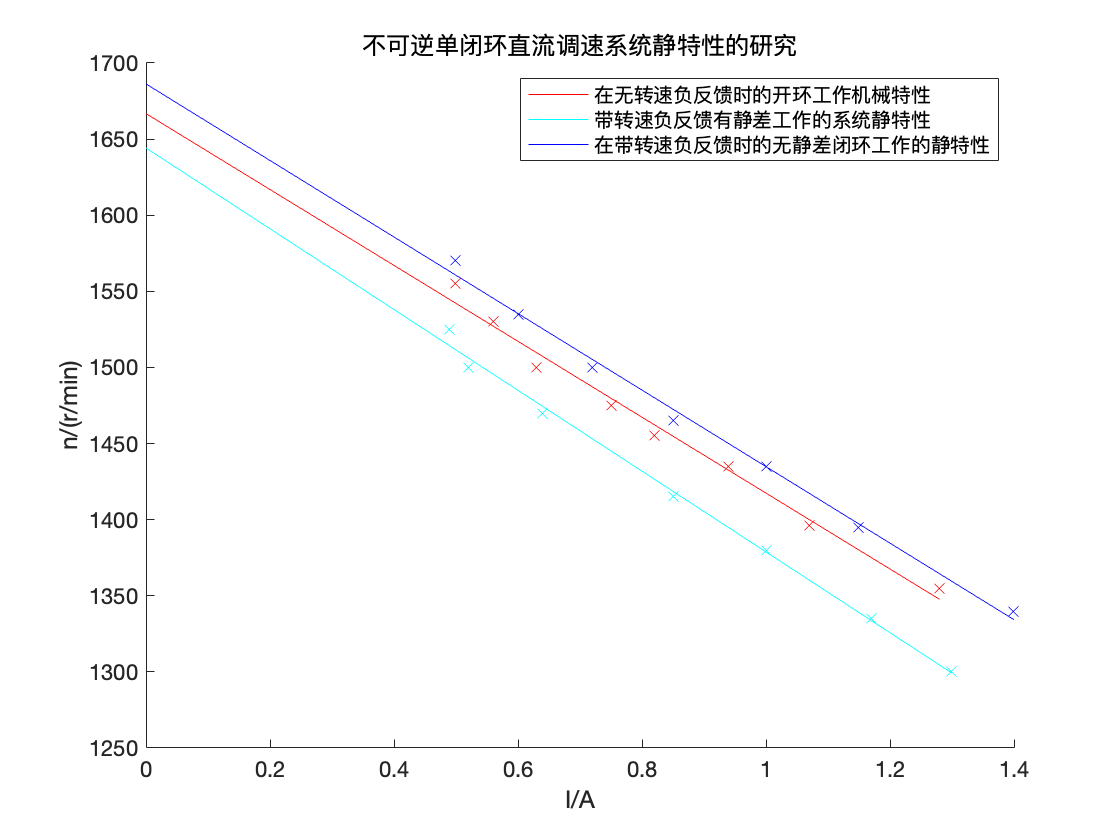

figure();
hold on;
labels={'在无转速负反馈时的开环工作机械特性',...
    '带转速负反馈有静差工作的系统静特性',...
    '在带转速负反馈时的无静差闭环工作的静特性'};
ps=zeros(3);
specs={'r','c','b'};
for i=1:3
    data=readmatrix("exprData.xlsx","Sheet",sheets(i));
    I=data(1,2:end);
    u=data(2,2:end);
    n=data(3,2:end);
    p=polyfit(I,n,1);
    x=[0,I];
    f = polyval(p,x); 
    plot(I,n,strcat(specs{i},'x'));
    ps(i)=plot(x,f,strcat(specs{i},'-'));
end
xlabel('I/A');
ylabel('n/(r/min)');
legend(ps(1:3),labels);
title('不可逆单闭环直流调速系统静特性的研究');